# Ped-Bro

## Connect server to Import DATA

% โหลดไฟล์เสียง: อ่านไฟล์เสียงจาก URL หรือไฟล์ในเครื่อง
url = 'https://archive.org/download/windows-10-sounds/Alarm01.wav'; 
filename = 'Alarm01.wav';

# Read Audio

frameLength = 1024;

% Using dsp.AudioFileReader  
% เริ่มการอ่านไฟล์เสียง
wavetest = "Exsamples\Day2.wav";
fileReader = dsp.AudioFileReader("Exsamples\Day2.wav", 'SamplesPerFrame', frameLength);
[audioData, Fs] = audioread("Exsamples\Day2.wav");

syncThreshold = db2mag(-30);  % Threshold for SYNC signal


deviceReader = audioDeviceReader(Fs, frameLength);

deviceWriter = audioDeviceWriter('SampleRate', Fs);
% plot(audioData);
player = audioplayer(audioData, Fs); % must specify correct sampling rate
play(player);

stop(player) 

% ตั้งค่าสำหรับการแสดงผล (ถ้าต้องการ)
scope = timescope('SampleRate', Fs, 'TimeSpan', 2, 'BufferLength', Fs * 2, ...
                  'YLimits', [-1, 1], 'TimeSpanOverrunAction', 'scroll');

bufferLength = round(0.5 * Fs); % buffer ประมาณ 5 วินาที
audioBuffer = zeros(1, bufferLength);
bufferPosition = 1;
audioPositionSinceSync = 1;
maxPeak = 0.0;
startThreshold = db2mag(-30);

% Wait for SYNC signal (sinusoid with amplitude larger than -30 dBFS) 
% รอการตรวจจับสัญญาณ SYNC
while ~isDone(fileReader)
    signal = fileReader(); % read a new frame
    if max(signal) > startThreshold
        maxPeak = max(signal);
        break;
    end
end

signal

signal =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


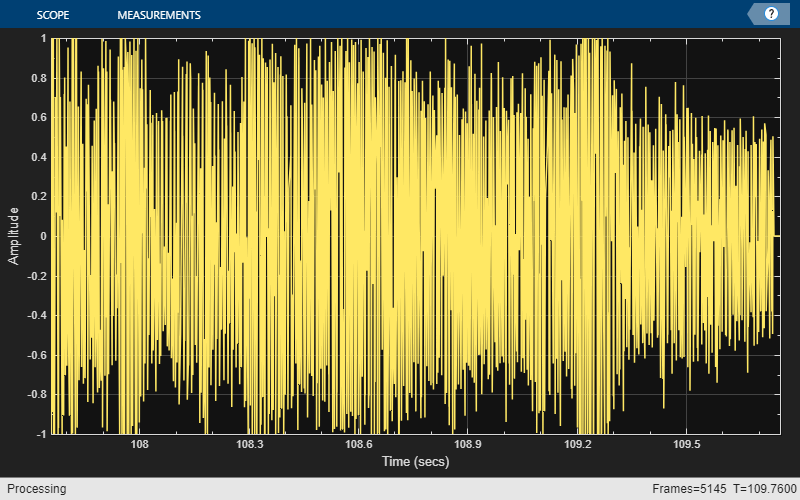

% ประมวลผลเสียงหลังจากเจอสัญญาณ SYNC
events = table('Size', [0 2], 'VariableTypes', {'double', 'categorical'}, ...
               'VariableNames', {'Position', 'Classification'});

while ~isDone(fileReader)
    signal = fileReader(); % read a new frame (อ่าน frame)

    % Adaptive normalization
    % ทำ normalization ตามค่าสูงสุด (peak)
    signalPeak = max(signal);
    if signalPeak > maxPeak
        maxPeak = signalPeak;
    end
    signal = signal / maxPeak; % scale the signal towards 1.0

    % Handle audio buffer
    % จัดการ buffer
    frameLength = length(signal);
    emptyLength = bufferLength - bufferPosition + 1;
    % Make space for the new frame 
    if emptyLength < frameLength
        moveOffset = frameLength - emptyLength;
        audioBuffer(1:bufferPosition-moveOffset-1) = audioBuffer(moveOffset+1:bufferPosition-1);
        bufferPosition = bufferPosition - moveOffset;
    end
    % Fill in the buffer with the new frame
    audioBuffer(bufferPosition:bufferPosition+frameLength-1) = signal;
    audioPositionSinceSync = audioPositionSinceSync + frameLength;
    bufferPosition = bufferPosition + frameLength;

    % Process audio in the buffer (event detection)
    % การตรวจจับและจำแนกเหตุการณ์ (placeholder)
    % ใส่ตรรกะการตรวจจับเหตุการณ์ที่นี่ โดยอาจดูจากคุณสมบัติของเสียง
    % ตัวอย่างเช่น ตรวจจับ peaks หรือลักษณะเฉพาะทางความถี่
    % แทนที่ส่วนนี้ด้วยโค้ดการจำแนกจริงของคุณ
    % ตรวจจับการเกิด event
    isStamping = false;  % ตัวอย่างเงื่อนไขการตรวจจับ event
    % ใช้ RMS หรือการตรวจจับการข้าม threshold เพื่อดูว่ามีการเกิด event หรือไม่
    shortRMS = dsp.MovingRMS(1024);  % กำหนดขนาดของ window
    rmsValue = shortRMS(signal);

    if max(rmsValue) > 0.3  % ตัวอย่างเงื่อนไขที่บ่งชี้ว่าเกิด event
        isStamping = true;
    end

    % บันทึก event หากมีการตรวจจับ
    if isStamping
        eventPosition = audioPositionSinceSync;  % ตำแหน่ง event
        % หากตรวจพบ event ให้บันทึกสถานะ
        if rmsValue(end) > 0.5  % ตัวอย่างเงื่อนไขว่าเป็น event แบบ Faulty
            eventClass = 'F';  % Faulty
        else
            eventClass = 'N';  % Normal
        end
        events = [events; {eventPosition, categorical(cellstr(eventClass))}];
        
    end
    % deviceWriter(signal);
    scope(signal);
    
end

% Convert the Position column to integers if the values are integer-like
events.Position = round(events.Position);  % Round to ensure integer values if needed

# Save to Excel

% Save to Excel
writetable(events, 'stamping_events.xlsx');
disp('บันทึกไฟล์ stamping_events.xlsx เรียบร้อยแล้ว');

บันทึกไฟล์ stamping_events.xlsx เรียบร้อยแล้ว


events

events = 1976×2 table
    Position    Classification
    ________    ______________

      1025            F       
      2049            F       
      3073            F       
      4097            F       
      5121            F       
     12289            F       
     13313            F       
     14337            F       
     15361            F       
     16385            F       
     17409            F       
     18433            F       
     19457            N       
     20481            N       
     28673            N       
     29697            N       


## Real-time audio processing loop

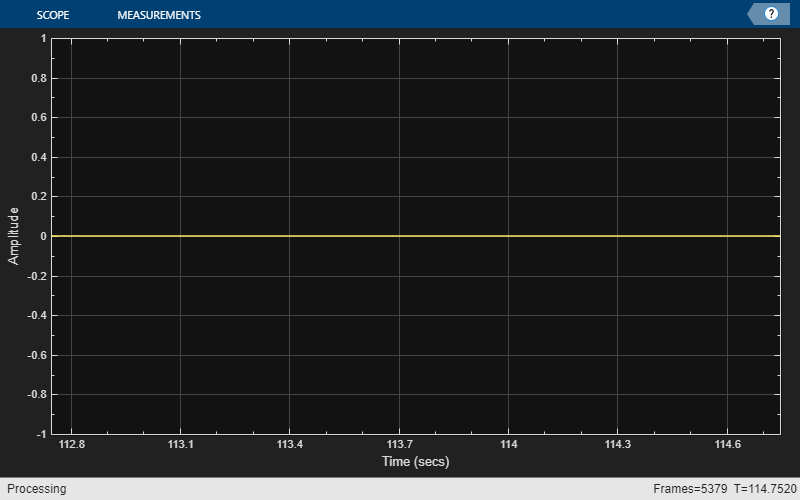

processingTime = 5.0; % seconds                                                                                             
frameCount = processingTime * Fs / frameLength;
for i = 1:frameCount
    signal = deviceReader();

    % Perform normalization and buffering
    % Process audio buffer
    % Segment, classify, and report results

    deviceWriter(signal);
    scope(signal);
end

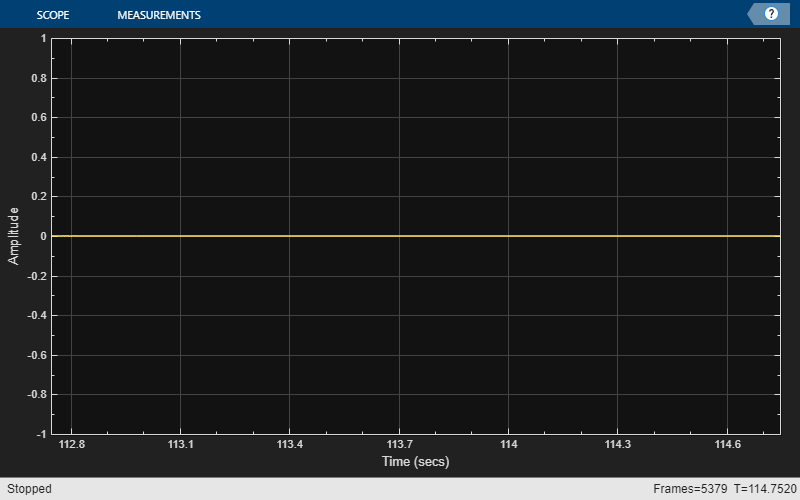

release(scope);

release(fileReader);
release(deviceReader);
release(deviceWriter);

# การระบุตำแหน่ง Event

- ใช้การข้ามผ่าน threshold ของเส้นสัญญาณ

- ใช้การ crossing (ตัดกัน) ของเส้นสัญญาณสองเส้นหรือมากกว่า

## การใช้ moving RMS ในการหาตำแหน่ง event

Moving RMS และ DWT จะช่วยในการวิเคราะห์รูปแบบของสัญญาณเพื่อหาตำแหน่งที่มีการเปลี่ยนแปลงที่น่าจะเป็นเหตุการณ์

- คำนวณ Moving RMS:  คำนวณค่า RMS ของสัญญาณในช่วงเวลาสั้นๆ แบบเคลื่อนที่

- กำหนด Threshold: กำหนดค่า Threshold ของ RMS

- ตรวจจับ Event:  เมื่อค่า RMS เกิน Threshold  ถือว่าเกิด Event

- ข้อดี:  เหมาะกับสัญญาณที่มีการเปลี่ยนแปลงของพลังงาน

- ข้อเสีย:  อาจต้องปรับแต่งขนาดของ window

audioData = audioread(wavetest);

shortWinLength = round(0.3 * Fs);
longWinLength = round(2.0 * Fs);

shortRMS = dsp.MovingRMS(shortWinLength);
longRMS = dsp.MovingRMS(longWinLength);

% กำหนดช่วงเวลา 5 วินาทีแรก (ในหน่วย sample)
startSample = 1;
endSample = round(50 * Fs);  % กำหนดนาที

% ตัดเฉพาะเวลาที่เลือก
audioData = audioData(startSample:endSample);

env1 = shortRMS(audioData);
env2 = longRMS(audioData);

% แสดงผลข้อมูลที่ตัดออกมา
figure;
%plot(audioDataSec);
%title('First 5 Seconds of Audio');

จุดตัดเมื่อชดเชยการเลื่อนของเวลา (ครึ่งของความยาว window)

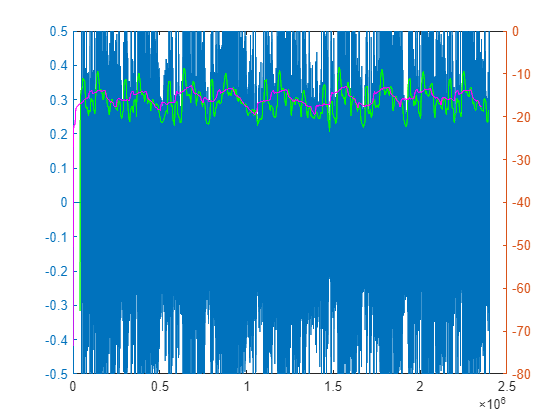

shortOffset = round(shortWinLength/2);
longOffset = round(longWinLength/2);

figure;
yyaxis left;
plot(audioData);
hold on;
yyaxis right;
plot(mag2db(env1(shortOffset:end)), 'g-');
plot(mag2db(env2(longOffset:end)), 'm-');
hold off;

# การใช้ DWT ในการหาตำแหน่ง event

- ใช้ maximal overlap DWT (MODWT) ซึ่งจะไม่ลดสเกลเวลาในแต่ละระดับ

- แปลงสัญญาณด้วย DWT:  ใช้ Discrete Wavelet Transform (DWT) เพื่อวิเคราะห์สัญญาณในโดเมนเวลา-ความถี่

- วิเคราะห์ค่าสัมประสิทธิ์:  วิเคราะห์ค่าสัมประสิทธิ์ wavelet  เพื่อหาตำแหน่งที่มีการเปลี่ยนแปลงอย่างรวดเร็ว  ซึ่งอาจบ่งชี้ถึง Event

- ข้อดี:  สามารถวิเคราะห์สัญญาณที่ซับซ้อนได้ดี

- ข้อเสีย:  การเลือก wavelet  และ  level  ที่เหมาะสม  อาจมีความซับซ้อน

wt = modwt(audioData, 'db2', 'TimeAlign', true);
% wt = modwt(audioData, 'db2', 14, 'TimeAlign', true); % with level limit
size(wt)

ans =           22     2400000


เสียงต้นฉบับและ DWT ที่ระดับต่าง ๆ (แสดงระดับที่ 11-14)

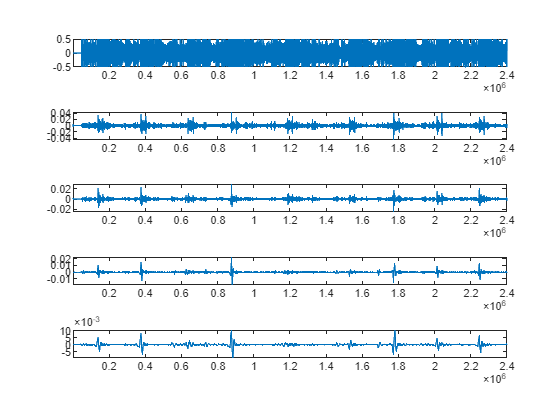

subplot(5, 1, 1);
plot(audioData);
axis tight;
for k = 11:14
    subplot(5, 1, k-9);
    plot(wt(k,:));
    axis tight;
    if k == 1
        title("MODWT Analysis");
    end
end

% First levels

[cA, cD] = dwt(audioData, 'db2');

length(cA)

ans = 1200001

length(cD)

ans = 1200001

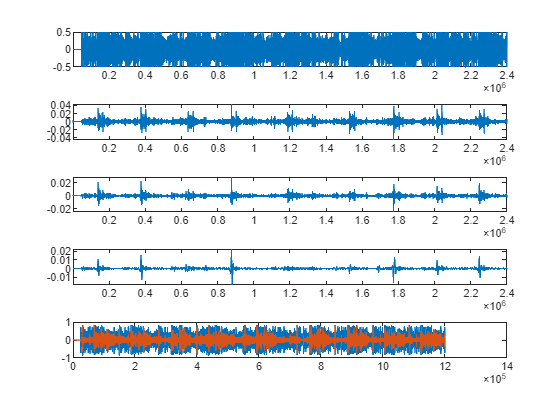


plot(cA);
hold on;
plot(cD);                                                                                                                                                                   
hold off;

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B4770";

% Specify column names and types
opts.VariableNames = ["Position", "Classification"];
opts.VariableTypes = ["double", "categorical"];

% Specify variable properties
opts = setvaropts(opts, "Classification", "EmptyFieldRule", "auto");

% Import the data
Ped_Bro = readtable("stamping_events.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
Ped_Bro

Ped_Bro = 4769×2 table
    Position    Classification
    ________    ______________

      1025            F       
      2049            F       
      3073            F       
      4097            F       
      5121            F       
     12289            F       
     13313            F       
     14337            F       
     15361            F       
     16385            F       
     17409            F       
     18433            F       
     19457            N       
     20481            N       
     28673            N       
     29697            N       


# **2. การตัดแยกเสียงเมื่อเกิดเหตุการณ์**

### คุณสามารถใช้ตาราง `stamping_events` เพื่อเข้าถึงตำแหน่งของเหตุการณ์แล้วทำการตัดเสียง

% โหลดข้อมูลจาก Excel ที่บันทึกไว้
opts = spreadsheetImportOptions("NumVariables", 2);
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B4770";
opts.VariableNames = ["Position", "Classification"];
opts.VariableTypes = ["double", "categorical"];
opts = setvaropts(opts, "Classification", "EmptyFieldRule", "auto");

Ped_Bro = readtable("stamping_events.xlsx", opts, "UseExcel", false);

% แสดงผลข้อมูลเหตุการณ์
disp(Ped_Bro);

     Position     Classification
    __________    ______________

          1025     F            
          2049     F            
          3073     F            
          4097     F            
          5121     F            
         12289     F            
         13313     F            
         14337     F            
         15361     F            
         16385     F            
         17409     F            
         18433     F            
         19457     N            
         20481     N            
         28673     N            
         29697     N            
         30721     N            
         50177     N            
         51201     N            
         60417     N            
         61441     F            
         62465     N            
         75777     N            
         76801     N            
         84993     N            
         88065     F            
       

% กำหนดค่า sample rate
Fs = 48000;

% ตั้งค่าความยาวของช่วงเวลาที่จะตัด (เช่น 0.5 วินาที)
eventWindow = round(0.5 * Fs);  % 0.5 วินาที

% สร้างตัวแปรเพื่อเก็บเสียงที่ตัดออกมา
segmentedAudio = {};

% การตัดแยกเสียงตามเหตุการณ์
for i = 1:height(Ped_Bro)
    % ดึงตำแหน่งของเหตุการณ์
    eventPos = Ped_Bro.Position(i);

    % ตรวจสอบว่าเหตุการณ์ไม่เกินขอบเขตของไฟล์เสียง
    if eventPos > eventWindow && eventPos < length(audioData) - eventWindow
        % ตัดช่วงเวลาของเสียงจากตำแหน่งเหตุการณ์
        segment = audioData(eventPos - eventWindow:eventPos + eventWindow - 1, :);
        
        % บันทึกเสียงที่ตัดออกมา
        segmentedAudio{end+1} = segment;
        
        % แสดงผลว่าได้ตัดเสียงในช่วงไหน
        disp(['ตัดเสียงจากตำแหน่ง: ', num2str(eventPos)]);
    end
end

ตัดเสียงจากตำแหน่ง: 28673
ตัดเสียงจากตำแหน่ง: 29697
ตัดเสียงจากตำแหน่ง: 30721
ตัดเสียงจากตำแหน่ง: 50177
ตัดเสียงจากตำแหน่ง: 51201
ตัดเสียงจากตำแหน่ง: 60417
ตัดเสียงจากตำแหน่ง: 61441
ตัดเสียงจากตำแหน่ง: 62465
ตัดเสียงจากตำแหน่ง: 75777
ตัดเสียงจากตำแหน่ง: 76801
ตัดเสียงจากตำแหน่ง: 84993
ตัดเสียงจากตำแหน่ง: 88065
ตัดเสียงจากตำแหน่ง: 89089
ตัดเสียงจากตำแหน่ง: 90113
ตัดเสียงจากตำแหน่ง: 91137
ตัดเสียงจากตำแหน่ง: 92161
ตัดเสียงจากตำแหน่ง: 93185
ตัดเสียงจากตำแหน่ง: 94209
ตัดเสียงจากตำแหน่ง: 95233
ตัดเสียงจากตำแหน่ง: 96257
ตัดเสียงจากตำแหน่ง: 97281
ตัดเสียงจากตำแหน่ง: 98305
ตัดเสียงจากตำแหน่ง: 99329
ตัดเสียงจากตำแหน่ง: 100353
ตัดเสียงจากตำแหน่ง: 101377
ตัดเสียงจากตำแหน่ง: 102401
ตัดเสียงจากตำแหน่ง: 103425
ตัดเสียงจากตำแหน่ง: 104449
ตัดเสียงจากตำแหน่ง: 105473
ตัดเสียงจากตำแหน่ง: 106497
ตัดเสียงจากตำแหน่ง: 107521
ตัดเสียงจากตำแหน่ง: 108545
ตัดเสียงจากตำแหน่ง: 109569
ตัดเสียงจากตำแหน่ง: 110593
ตัดเสียงจากตำแหน่ง: 111617
ตัดเสียงจากตำแหน่ง: 112641
ตัดเสียงจากตำแหน่ง: 113665
ตัดเสียงจากตำแหน่ง: 1146


% ตัวอย่างการบันทึกเสียงที่ตัดออกมา (บันทึกไฟล์เสียงที่ตัดแยกออกมา)
for i = 1:length(segmentedAudio)
    filename = sprintf('event_segment_%d.wav', i);
    % audiowrite(filename, segmentedAudio{i}, Fs); !!!!! ระวัง File save
    % disp(['บันทึกเสียง: ', filename]);
end
